clear; clc; close all
%% Radar parameters
c = physconst('LightSpeed'); %speed of light
BW = 50e6; %bandwidth
fc = 3000e6; % carrier frequency
numADC = 1000; % # of adc samples
numChirps = 256; % # of chirps per frame

numCPI = 10;
T = 10e-3; % PRI 
PRF = 1/T;
F = numADC/T; % sampling frequency
dt = 1/F; % sampling interval
slope = BW/T;
lambda = c/fc;


N = numChirps*numADC*numCPI; % total # of adc samples
t = linspace(0,T*numChirps*numCPI,N); % time axis, one frame
t_onePulse = 0:dt:dt*numADC-dt;

% Ny=4;
Ny=4;
numTX = 4;
numRX = 4;

N_L=floor(2*fc/BW);
(mod(N_L, 2) == 0)*(N_L-1)+(mod(N_L, 2) == 1)*(N_L) % 扩展的虚拟阵列

ans = 119

N_L=1;

d_y=lambda/2/2;
d_tx= lambda/2;
d_rx = numRX*d_tx; % dist. between rxs
% d_tx = 4*d_rx; % dist. between txs

% tr_vel=-d_tx/2/T;
tr_vel=0;

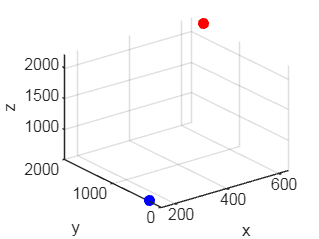


%% Targets

r1_radial = 2900;
tar1_theta = 40;
tar1_phi= 70;
r1_x = cosd(tar1_phi)*sind(tar1_theta)*r1_radial;
r1_y = sind(tar1_phi)*sind(tar1_theta)*r1_radial;
r1_z = cosd(tar1_theta)*r1_radial;

v1_radial = 0.001; % velocity 1
v1_x = cosd(tar1_phi)*cosd(tar1_theta)*v1_radial;
v1_y = sind(tar1_phi)*cosd(tar1_theta)*v1_radial;
v1_z = sind(tar1_theta)*v1_radial;
r1 = [r1_x r1_y r1_z];


tar1_loc = zeros(length(t),3);
tar1_loc(:,1) = r1(1) + v1_x*t;
tar1_loc(:,2) = r1(2) + v1_y*t;
tar1_loc(:,3) = r1(3) + v1_z*t;

scatter3(tar1_loc(1,1),tar1_loc(1,2),tar1_loc(1,3),'r','filled')
hold on

r2_radial = 600;
tar2_theta = 30;
tar2_phi = 60;
r2_x = cosd(tar2_phi)*sind(tar2_theta)*r2_radial;
r2_y = sind(tar2_phi)*sind(tar2_theta)*r2_radial;
r2_z = cosd(tar2_theta)*r2_radial;

v2_radial = 0.1; % velocity 1
v2_x = cosd(tar2_phi)*sind(tar2_theta)*v2_radial;
v2_y = sind(tar2_phi)*sind(tar2_theta)*v2_radial;
v2_z = cosd(tar2_theta)*v2_radial;
r2 = [r2_x r2_y r2_z];


tar2_loc = zeros(length(t),3);
tar2_loc(:,1) = r2(1) + v2_x*t;
tar2_loc(:,2) = r2(2) + v2_y*t;
tar2_loc(:,3) = r2(3) + v2_z*t;

scatter3(tar2_loc(1,1),tar2_loc(1,2),tar2_loc(1,3),'blue','filled')
xlabel('x');
ylabel('y');
zlabel('z');
hold off

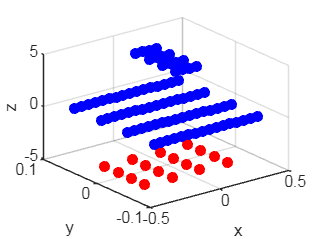

tx_loc = cell(numTX,Ny);
tx_loc_t=cell(numTX,Ny);
for j=1:Ny
    for i = 1:numTX
        % tx_loc{i,j} = [(i-1)*d_tx (j-1)*d_y 0];
        tx_loc{i,j} = [(i-1)*d_tx-((numTX-1)*d_tx)/2 (j-1)*d_y-((Ny-1)*d_y)/2 5];

        tx_loc_t{i,j}=zeros(length(t),3);
        tx_loc_t{i,j}(:,1)=tr_vel*t+tx_loc{i,j}(1);
        tx_loc_t{i,j}(:,2)=tx_loc{i,j}(2);
        tx_loc_t{i,j}(:,3)=tx_loc{i,j}(3);
    
        scatter3(tx_loc{i,j}(1),tx_loc{i,j}(2),tx_loc{i,j}(3),'b','filled')
       hold on
    end
end

rx_loc = cell(numRX,Ny);
rx_loc_t=cell(numRX,Ny);
for j = 1 : Ny
    for i = 1 : numRX
        % rx_loc{i,j} = [tx_loc{numTX,1}(1)+d_tx+(i-1)*d_rx (j-1)*d_y 0];
        rx_loc{i,j} = [(i-1)*d_rx-((numRX-1)*d_rx)/2 (j-1)*d_y-((Ny-1)*d_y)/2 -5];
        rx_loc_t{i,j}=zeros(length(t),3);
        rx_loc_t{i,j}(:,1)=tr_vel*t+rx_loc{i,j}(1);
        rx_loc_t{i,j}(:,2)=rx_loc{i,j}(2);
        rx_loc_t{i,j}(:,3)=rx_loc{i,j}(3);
        scatter3(rx_loc{i,j}(1),rx_loc{i,j}(2),rx_loc{i,j}(3),'r','filled')
    end
end
xlabel('x');
ylabel('y');
zlabel('z');



plane_loc=cell(numTX*numRX,Ny);
for i =1:numTX
    for k = 1:numRX
        for j = 1:Ny
            plane_loc{i+(k-1)*numTX,j}=rx_loc{k,j}+tx_loc{i,j};
            scatter3(plane_loc{i+(k-1)*numTX,j}(1),plane_loc{i+(k-1)*numTX,j}(2),plane_loc{i+(k-1)*numTX,j}(3),'b','filled')
            hold on
        end
    end
end
hold off

% plane_loc_plus=cell(numTX*numRX+N_L-1,Ny);
% for i =1:numTX*numRX+N_L-1
%     for j=1:Ny
%         if i<=(N_L-1)/2           
%              plane_loc_plus{i,j}(1)=plane_loc{i+(N_L-1)/2,j}(1)-d_tx*((N_L-1)/2+1-i);    
%         end
%     end
% end

P1 = rx_loc{1,1};
P2 = r1;


% 计算两点之间的距离
d = sqrt((P2(1) - P1(1))^2 + (P2(2) - P1(2))^2 + (P2(3) - P1(3))^2);

% 计算仰角
theta = asin((P2(3) - P1(3)) / d); % 仰角，单位为弧度

% 计算方向角
phi = atan2(P2(2) - P1(2), P2(1) - P1(1)); % 方向角，单位为弧度

% 如果需要，可以将弧度转换为度
theta_deg = rad2deg(theta);
phi_deg = rad2deg(phi);

% 输出结果
fprintf('仰角 (弧度): %.4f\n', theta);

仰角 (弧度): 0.8737


fprintf('方向角 (弧度): %.4f\n', phi);

方向角 (弧度): 1.2216


fprintf('仰角 (度): %.4f\n', theta_deg);

仰角 (度): 50.0613


fprintf('方向角 (度): %.4f\n', phi_deg);

方向角 (度): 69.9917


%% TX

delays_tar1 = cell(numTX,numRX,Ny);
delays_tar2 = cell(numTX,numRX,Ny);
for k = 1:Ny
    for i = 1:numTX
        for j = 1:numRX
            delays_tar1{i,j,k} = (vecnorm(tar1_loc-rx_loc_t{j,k},2,2) ...
                            +vecnorm(tar1_loc-tx_loc_t{i,k},2,2))/c; 
            delays_tar2{i,j,k} = (vecnorm(tar2_loc-rx_loc_t{j,k},2,2) ...
                            +vecnorm(tar2_loc-tx_loc_t{i,k},2,2))/c;
        end
    end
end


% r1_at_t = cell(numTX,numRX);
% r2_at_t = cell(numTX,numRX);
% tar1_angles = cell(numTX,numRX);
% tar2_angles = cell(numTX,numRX);
% tar1_velocities = cell(numTX,numRX);
% tar2_velocities = cell(numTX,numRX);


%% Complex signal
phase = @(tx,fx) 2*pi*(fx.*tx+slope/2*tx.^2); % transmitted
snr=20;

mixed = cell(numTX,numRX,Ny);
% for l = 1:Ny
%     for i = 1:numTX
%         for j = 1:numRX
%             % disp(['Processing Channel: ' num2str(j) '/' num2str(numRX)]);
%             for k = 1:numChirps*numCPI
%                 phase_t = phase(t_onePulse,fc);
%                 phase_1 = phase(t_onePulse-delays_tar1{i,j,l}(k*numADC),fc); % received
%                 phase_2 = phase(t_onePulse-delays_tar2{i,j,l}(k*numADC),fc);
% 
%                 signal_t((k-1)*numADC+1:k*numADC) = exp(1j*phase_t);
%                 signal_1((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_1));
%                 signal_2((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_2));
%             end
%             % mixed{i,j,l} = signal_1 + signal_2;
%             % mixed{i,j,l} = signal_1 ;
%             mixed{i,j,l} =awgn(signal_1+ signal_2,snr,'measured');
%         end
%     end
% end

% 假设变量已定义: numTX, numRX, Ny, numChirps, numCPI, numADC, fc, t_onePulse, delays_tar1, delays_tar2, snr

numSamplesPerChirp = numADC;
numChirpsTotal = numChirps * numCPI; % 总的chirp/CPI段数
numSamplesTotal = numChirpsTotal * numSamplesPerChirp; % 每个通道的总样本数

mixed = cell(numTX, numRX, Ny); % 预分配结果单元数组

% 确保 t_onePulse 是一个行向量，以便进行广播/隐式扩展
t_onePulse_row = reshape(t_onePulse, 1, numSamplesPerChirp);

% --- 外层循环仍然保留 ---
for l = 1:Ny
    for i = 1:numTX
        for j = 1:numRX
            % --- 向量化内部计算 ---

            % 获取当前通道对应的延迟向量 (假设长度为 numChirpsTotal)
            % 注意：如果原始索引 k*numADC 有特殊含义，需要相应调整这里的索引
            current_delays1 = delays_tar1{i, j, l}(1:numChirpsTotal); % 取前 numChirpsTotal 个延迟
            current_delays2 = delays_tar2{i, j, l}(1:numChirpsTotal); % 取前 numChirpsTotal 个延迟

            % 将延迟向量变为列向量，以便与行向量 t_onePulse_row 进行隐式扩展
            current_delays1_col = reshape(current_delays1, numChirpsTotal, 1);
            current_delays2_col = reshape(current_delays2, numChirpsTotal, 1);

            % --- 计算信号 ---
            % 利用隐式扩展 (implicit expansion, R2016b+) 或 bsxfun (旧版本)
            % 计算每个 chirp 段的基准相位 (对所有 chirp 都相同)
            % phase_t_matrix 的维度将是 [numChirpsTotal, numSamplesPerChirp]
            phase_t_matrix = phase(t_onePulse_row, fc); % 实际上 phase_t 对每个chirp段内部点是一样的

            % 计算每个 chirp 段接收信号的相位 (考虑延迟)
            % t_onePulse_row (1 x N_adc) - current_delays1_col (N_chirp x 1)
            % 结果维度是 [numChirpsTotal, numSamplesPerChirp]
            phase_1_matrix = phase(t_onePulse_row - current_delays1_col, fc);
            phase_2_matrix = phase(t_onePulse_row - current_delays2_col, fc);

            % 计算相位差并得到复信号矩阵
            % phase_t_matrix 会自动扩展以匹配 phase_1_matrix 和 phase_2_matrix 的维度
            signal_1_matrix = exp(1j * (phase_t_matrix - phase_1_matrix));
            signal_2_matrix = exp(1j * (phase_t_matrix - phase_2_matrix));

            % 将信号矩阵按列优先顺序（MATLAB默认）展开成长向量
            % 需要转置使其按行填充，再reshape
            signal_1 = reshape(signal_1_matrix.', numSamplesTotal, 1);
            signal_2 = reshape(signal_2_matrix.', numSamplesTotal, 1);

            % --- 组合信号并添加噪声 ---
            % 根据原始代码的注释，选择是加和还是只用 signal_1
            % mixed_signal = signal_1 + signal_2;
            mixed_signal = signal_1+signal_2;

            % 添加 AWGN 噪声
            mixed{i, j, l} = awgn(mixed_signal, snr, 'measured');

        end % 结束 j 循环
    end % 结束 i 循环
end % 结束 l 循环

% --- 清理临时变量 (可选) ---
clear t_onePulse_row phase_t_matrix phase_1_matrix phase_2_matrix signal_1_matrix signal_2_matrix signal_1 signal_2 mixed_signal current_delays1 current_delays2 current_delays1_col current_delays2_col numSamplesPerChirp numChirpsTotal numSamplesTotal;



% 
% figure
% subplot(3,1,1)
% p1 = plot(t, real(signal_t));
% title('TX')
% xlim([0 0.1e-1])
% xlabel('Time (sec)');
% ylabel('Amplitude');
% subplot(3,1,2)
% p2 = plot(t, real(signal_1));
% title('RX')
% xlim([0 0.1e-1])
% xlabel('Time (sec)');
% ylabel('Amplitude');
% subplot(3,1,3)
% p3 = plot(t,real(mixed{1,1,1}));
% title('Mixed')
% xlim([0 0.1e-1])
% xlabel('Time (sec)');
% ylabel('Amplitude');

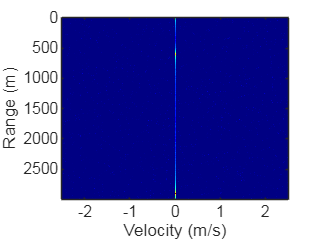


%% Post processing - 2-D FFT



RDC = reshape(cat(3,mixed{:}),numADC,numChirps*numCPI,numRX*numTX*Ny); % radar data cube


RDC_plus=RDC;

% numChirps_new=(numChirps-(N_L-1));
numChirps_new=numChirps;
DFmax = 1/2*PRF; % = Vmax/(c/fc/2); % Max Unamb Dopp Freq
dR = c/(2*BW); % range resol
Rmax = F*c/(2*slope); % TI's MIMO Radar doc
Rmax2 = c/2/PRF; % lecture 2.3

dV = lambda/(2*numChirps*T); % velocity resol, lambda/(2*framePeriod)
Vmax = lambda/(T*4); % Max Unamb velocity m/s

N_Dopp = numChirps_new; % length of doppler FFT
N_range = numADC; % length of range FFT
N_azimuth = (numRX*numTX+N_L-1)*Ny;
R = 0:dR:Rmax-dR; % range axis
V = linspace(-Vmax, Vmax, numChirps_new); % Velocity axis


ang_phi = -180:0.1:180; % angle axis
ang_theta=0:0.1:90;


RDMs = zeros(numADC,numChirps_new,(numRX*numTX+N_L-1)*Ny,numCPI);
for i = 1:numCPI
    RD_frame = RDC_plus(:,(i-1)*numChirps_new+1:i*numChirps_new,:);
    RDMs(:,:,:,i) = fftshift(fft2(RD_frame,N_range,N_Dopp),2);
    % RDMs(:,:,:,i) = RD_frame;
end




figure
imagesc(V,R,20*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1))))));
colormap(jet(256))
% set(gca,'YDir','normal')
clim = get(gca,'clim');
caxis([clim(1)/2 0])
xlabel('Velocity (m/s)');
ylabel('Range (m)');

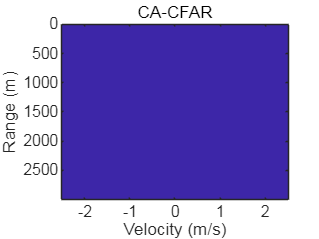


%% CA-CFAR

numGuard = 2; % # of guard cells
numTrain = numGuard*2; % # of training cells
P_fa = 1e-5; % desired false alarm rate 
SNR_OFFSET = -5; % dB
RDM_dB = 10*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1)))));

[RDM_mask, cfar_ranges, cfar_dopps, K] = ca_cfar(RDM_dB, numGuard, numTrain, P_fa, SNR_OFFSET);
cfar_ranges_real=(cfar_ranges-1)*3;
figure
h=imagesc(V,R,RDM_mask);
xlabel('Velocity (m/s)')
ylabel('Range (m)')
title('CA-CFAR')

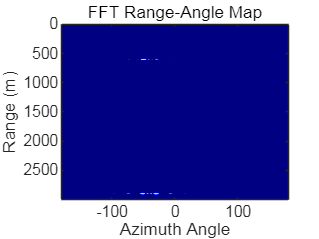


%% Angle Estimation - FFT

rangeFFT = fft(RDC_plus(:,1:numChirps_new,:),numADC);

angleFFT = fftshift(fft(rangeFFT,length(ang_phi),3),3);
range_az = squeeze(sum(angleFFT,2)); % range-azimuth map

figure
colormap(jet)
imagesc(ang_phi,R,20*log10(abs(range_az)./max(abs(range_az(:))))); 
xlabel('Azimuth Angle')
ylabel('Range (m)')
title('FFT Range-Angle Map')
set(gca,'clim', [-35, 0])

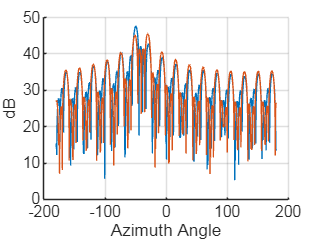


doas = zeros(K,length(ang_phi)); % direction of arrivals
figure
hold on; grid on;
for i = 1:K
    doas(i,:) = fftshift(fft(rangeFFT(cfar_ranges(i),cfar_dopps(i),:),length(ang_phi)));
    plot(ang_phi,10*log10(abs(doas(i,:))))
end
xlabel('Azimuth Angle')
ylabel('dB')


    % 
    % doas(1,:) = fftshift(fft(rangeFFT(cfar_ranges(1),cfar_dopps(1),:),length(ang_phi)));
    % plot(ang_phi,10*log10(abs(doas(1,:))))
% figure
% hold on; grid on;
% for i = 1:K
%     plot(ang_ax,abs(doas(i,:)))
% end
% xlabel('Azimuth Angle')



%% Angle Estimation - MUSIC Pseudo Spectrum


M = numCPI; % # of snapshots
% a1=zeros((numRX*numTX+N_L-1)*Ny,length(ang_theta)*length(ang_phi));
% for k = 1:numRX*numTX+N_L-1
%     for l = 1:Ny
%        for i=1:length(ang_theta)
%             for j=1:length(ang_phi)
%                 % a1(k+(l-1)*(numRX*numTX+N_L-1),i,j ...
%                 %     )=exp(-1i*2*pi*(d_y*(l-1)*cos(ang_phi(j).'*pi/180)*sin(ang_theta(i).'*pi/180) ...
%                 %     +d_tx*(k-1)*sin(ang_phi(j).'*pi/180)*sin(ang_theta(i).'*pi/180)));
%                 a1(k+(l-1)*(numRX*numTX+N_L-1),i+(j-1)*length(ang_theta) ...
%                     )=exp(-1i*2*pi/lambda*(d_y*2*(l-1)*sind(ang_phi(j))*sind(ang_theta(i)) ...
%                                    +d_tx*(k-1)*cosd(ang_phi(j))*sind(ang_theta(i)) ) );
%             end
%        end
%     end
% end

% 参数计算
N_theta = length(ang_theta);
N_phi = length(ang_phi);

% 提取所有天线位置坐标（从plane_loc中提取）
numAntennas = numTX * numRX; % 总天线数
M_num = numAntennas * Ny; % 总行数：天线数×快拍数
all_coords = zeros(M_num, 3); % 存储所有坐标点[x,y,z]

row = 1;
for j = 1:Ny
    for i_antenna = 1:numAntennas
        % 获取当前天线在j快拍的位置
        current_coord = plane_loc{i_antenna, j};
        all_coords(row, :) = current_coord;
        row = row + 1;
    end
end

% 生成所有角度组合 (theta, phi)
[theta_grid, phi_grid] = ndgrid(ang_theta, ang_phi);
theta_all = theta_grid(:);
phi_all = phi_grid(:);

% 计算波数向量（假设theta为俯仰角，phi为方位角）
kx = sind(theta_all) .* cosd(phi_all); % x方向分量
ky = sind(theta_all) .* sind(phi_all); % y方向分量
kz = cosd(theta_all);                 % z方向分量
k_matrix = [kx, ky, kz]; % 组合成N×3矩阵（N=N_theta*N_phi）

% 计算相位贡献：坐标与波数向量的点积
phase_contribution = all_coords * k_matrix.'; % M×N矩阵

% 计算复数相位并生成导向矩阵
% lambda = ...; % 确保此处已定义波长lambda
ph = (-1i * 2 * pi / lambda) .* phase_contribution;
a1 = exp(ph);


% % 参数计算
% nn = numRX * numTX + N_L - 1;
% Ny_val = Ny;
% N_theta = length(ang_theta);
% N_phi = length(ang_phi);
% 
% % 生成所有角度组合 (i,j)
% [theta_grid, phi_grid] = ndgrid(ang_theta, ang_phi);
% theta_all = theta_grid(:);
% phi_all = phi_grid(:);
% 
% % 计算列相关的项 (M = Nθ*Nφ)
% col_term_A = sind(phi_all) .* sind(theta_all);
% col_term_B = cosd(phi_all) .* sind(theta_all);
% 
% % 生成所有k和l的组合 (N = nn*Ny_val)
% [k_mesh, l_mesh] = ndgrid(0:(nn-1), 0:(Ny_val-1));
% k_vals = k_mesh(:);
% l_vals = l_mesh(:);
% 
% % 计算行相关的项
% row_term_A = d_y * 2 .* l_vals;
% row_term_B = d_tx .* k_vals;
% 
% % 矩阵相乘计算相位
% A_matrix = row_term_A * col_term_A.';
% 
% B_matrix = row_term_B * col_term_B.';
% phase = (-1i * 2 * pi / lambda) .* (A_matrix + B_matrix);
% 
% % 指数运算得到最终的a1矩阵
% a1 = exp(phase);


music_spectrum=zeros(K,length(ang_theta),length(ang_phi));
% 预计算参数
N_theta = length(ang_theta);
N_phi = length(ang_phi);
total_angles = N_theta * N_phi;
D = (numRX*numTX+N_L-1)*Ny;  % 协方差矩阵维度
noise_sub_dim = D - 1;       % 噪声子空间维度

% 预生成角度映射表
[theta_map, phi_map] = ndgrid(1:N_theta, 1:N_phi);
angle_indices = theta_map + (phi_map-1)*N_theta;

% 优化后的主循环
for i = 1:K
    % 矩阵化协方差计算
    B = reshape(RDMs(cfar_ranges(i), cfar_dopps(i), :, :), [], M);
    Rxx = (B * B') / M;
    
    % 特征分解优化
    [Q, D] = eig(Rxx, 'vector');
    [~, order] = sort(D, 'descend');
    Qn = Q(:, order(2:end));  % 直接获取噪声子空间
    
    % 批量计算所有角度组合
    QnH = Qn' * a1;  % 矩阵预乘
    denominator = sum(abs(QnH).^2, 1);
    numerator = sum(abs(a1).^2, 1);
    
    % 结果重塑
    music_spectrum(i,:,:) = reshape(numerator ./ denominator, N_theta,N_phi);
end



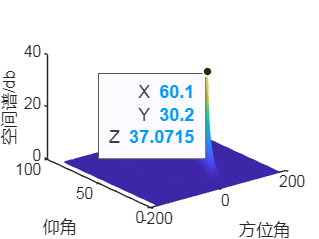


spectrum_data = 10 * log10(abs(reshape(music_spectrum(1,:,:), length(ang_theta), length(ang_phi))));

% 找到最大值及其索引
[max_value, max_index] = max(spectrum_data(:));
[row, col] = ind2sub(size(spectrum_data), max_index);

% 获取对应的角度
theta_max = ang_theta(row);
phi_max = ang_phi(col);

% reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi));
figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi,ang_theta,10*log10(abs(squeeze(music_spectrum(1,:,:)))));
ax = gca;
chart = ax.Children(1);
datatip(chart,phi_max,theta_max,max_value);
xlabel('方位角');ylabel('仰角');
zlabel('空间谱/db');
grid;

% 输出结果
fprintf('最高点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max, phi_max, max_value);

最高点坐标: (Theta: 30.20, Phi: 60.10), 强度: 37.07 dB


% fprintf('修正点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max-2, phi_max-2, max_value);

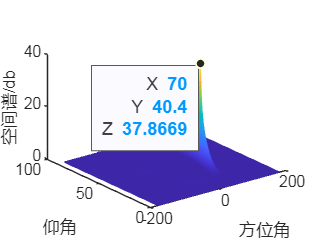


spectrum_data = 10 * log10(abs(reshape(music_spectrum(2,:,:), length(ang_theta), length(ang_phi))));

% 找到最大值及其索引
[max_value, max_index] = max(spectrum_data(:));
[row, col] = ind2sub(size(spectrum_data), max_index);

% 获取对应的角度
theta_max = ang_theta(row);
phi_max = ang_phi(col);
% reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi));

figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi,ang_theta,10*log10(abs(squeeze(music_spectrum(2,:,:)))));
ax = gca;
chart = ax.Children(1);
datatip(chart,phi_max,theta_max,max_value);
xlabel('方位角');ylabel('仰角');
zlabel('空间谱/db');
grid;



% 输出结果
fprintf('最高点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max, phi_max, max_value);

最高点坐标: (Theta: 40.40, Phi: 70.00), 强度: 37.87 dB


% fprintf('修正点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max-2, phi_max-2, max_value);


RDC_plus_rot_frame=RDC_plus(:,1:numChirps_new,:);

M = numCPI; % # of snapshots

A = reshape(squeeze(RDC_plus_rot_frame(:,1:100,:)),numADC*100,(numRX*numTX+N_L-1)*Ny);

Rxx = (A'*A);



[Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
[D, I] = sort(diag(D),'descend');
Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
Qs = Q(:,1); % Get the signal eigenvectors
Qn = Q(:,6:end); % Get the noise eigenvectors
% for j = 1:length(ang_theta)
%     for k = 1:length(ang_phi)
%         music_spectrum(2,j,k)=(a1(:,j+(k-1)*length(ang_theta))'*a1(:,j+(k-1)*length(ang_theta)))/(a1(:,j+(k-1)*length(ang_theta))'*(Qn*Qn')*a1(:,j+(k-1)*length(ang_theta)));
%     end
% end

% 预计算噪声空间投影矩阵
QnQn = Qn * Qn';

% 提取所有角度对应的导向矢量矩阵 (numElements x numAngles)
A_all = a1; % 维度 [numRX*numTX*(2*(N_L-1)+1), length(ang_theta)*length(ang_phi)]

% 批量计算分子：每个导向矢量的自相关 (等效||a||^2)
numerator = sum(conj(A_all) .* A_all, 1); % 结果为行向量 [1 x numAngles]

% 批量计算分母：a'*(QnQn)*a
QnQn_A = QnQn * A_all;                     % 矩阵乘法加速核心
denominator = sum(conj(A_all) .* QnQn_A, 1); % 结果为行向量 [1 x numAngles]

% 计算MUSIC谱并重塑为二维矩阵
music_spectrum_2D = reshape(numerator ./ denominator, length(ang_theta), length(ang_phi));



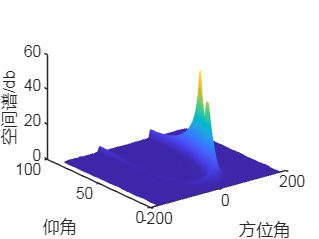

%% 方位角坐标修正
% 生成修正后的方位角坐标 (自动处理-180~180循环)
ang_phi_shifted = mod(ang_phi  +180+180, 360) - 180; 

%% 数据与坐标对齐
% 获取修正后坐标的排序索引（保证单调性）
[ang_phi_sorted, sort_idx] = sort(ang_phi_shifted);

% 对频谱数据按新方位角排序（沿phi轴重排）
spectrum_shifted = squeeze(music_spectrum_2D); 
spectrum_shifted = spectrum_shifted(:, sort_idx); 

% reshape(music_spectr2um(1,:,:),length(ang_theta),length(ang_phi));
figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi_sorted,ang_theta,10*log10(abs(spectrum_shifted)));
 
xlabel('方位角');ylabel('仰角');
zlabel('空间谱/db');
grid;



spectrum_data = 10 * log10(abs(reshape(spectrum_shifted, length(ang_theta), length(ang_phi))));

smoothed_spectrum=spectrum_data;

% 检测区域最大值
regional_max = imregionalmax(smoothed_spectrum);

% 获取峰值位置和数值
[max_rows, max_cols] = find(regional_max);
peak_values = smoothed_spectrum(regional_max);

% 合并信息并按峰值强度降序排序
peaks_info = sortrows([max_rows, max_cols, peak_values], -3);

% 提取前两个峰值
if size(peaks_info, 1) >= 1
    main_peak = peaks_info(1, :);
    fprintf('仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
            ang_theta(main_peak(1)), ang_phi_sorted(main_peak(2)));
        % fprintf('修正仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
        %     ang_theta(main_peak(1)), mod(ang_phi_sorted(main_peak(2))+360/N_num/numRX+180, 360) - 180);
end

仰角(theta)=40.30°，方位角(phi)=70.00°



if size(peaks_info, 1) >= 2
    second_peak = peaks_info(2, :);
    fprintf('仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
            ang_theta(second_peak(1)), ang_phi_sorted(second_peak(2)));
        % fprintf('修正仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
        %     ang_theta(second_peak(1)), mod(ang_phi_sorted(second_peak(2))+360/N_num/numRX+180, 360) - 180);
else
    disp('未找到明显的次峰值。');
end

仰角(theta)=30.30°，方位角(phi)=60.20°


%% 改进版抛物线插值函数（带边界检查）
function [refined_angle, is_valid] = safe_parabolic_interpolation(angles, spectrum_values)
    % 输入参数检查
    if numel(spectrum_values) < 3
        refined_angle = angles(round(numel(angles)/2));
        is_valid = false;
        return;
    end
    
    % 三点抛物线插值核心算法
    y1 = spectrum_values(1);
    y2 = spectrum_values(2);
    y3 = spectrum_values(3);
    denominator = y1 - 2*y2 + y3;
    
    % 防止分母过小导致数值不稳定
    if abs(denominator) < 1e-6
        refined_angle = angles(2);
        is_valid = false;
    else
        delta = 0.5 * (y1 - y3) / denominator;
        refined_angle = angles(2) + delta * (angles(2)-angles(1));
        is_valid = true;
    end
end

%% 改进后的峰值处理流程
% 初始化存储精确角度的矩阵
peaks_info = [peaks_info, zeros(size(peaks_info,1), 2)];

% 对每个检测到的峰值进行亚网格插值
for i = 1:size(peaks_info,1)
    row = peaks_info(i,1);
    col = peaks_info(i,2);
    
    %% 仰角(theta)方向插值 --------------------------------
    % 动态调整索引范围确保3个点
    theta_start = max(1, row-1);
    theta_end = min(length(ang_theta), row+1);
    if (theta_end - theta_start) < 2 % 边界补偿
        if theta_start == 1
            theta_end = min(theta_start+2, length(ang_theta));
        else
            theta_start = max(1, theta_end-2);
        end
    end
    
    theta_indices = theta_start:theta_end;
    theta_vals = ang_theta(theta_indices);
    spectrum_theta = smoothed_spectrum(theta_indices, col);
    
    % 执行安全插值
    [refined_theta, theta_valid] = safe_parabolic_interpolation(theta_vals, spectrum_theta);
    
    %% 方位角(phi)方向插值 --------------------------------
    % 动态调整索引范围确保3个点
    phi_start = max(1, col-1);
    phi_end = min(length(ang_phi_sorted), col+1);
    if (phi_end - phi_start) < 2 % 边界补偿
        if phi_start == 1
            phi_end = min(phi_start+2, length(ang_phi_sorted));
        else
            phi_start = max(1, phi_end-2);
        end
    end
    
    phi_indices = phi_start:phi_end;
    phi_vals = ang_phi_sorted(phi_indices);
    spectrum_phi = smoothed_spectrum(row, phi_indices);
    
    % 执行安全插值
    [refined_phi, phi_valid] = safe_parabolic_interpolation(phi_vals, spectrum_phi);
    
    %% 结果整合 ------------------------------------------
    if theta_valid && phi_valid
        peaks_info(i,4:5) = [refined_theta, refined_phi];
    else % 插值失败时使用原始网格值
        peaks_info(i,4:5) = [ang_theta(row), ang_phi_sorted(col)];
    end
end

%% 结果输出（示例）
if size(peaks_info, 1) >= 1
    fprintf('精确仰角: %.3f°, 精确方位角: %.3f°\n', peaks_info(1,4), peaks_info(1,5));
end

精确仰角: 40.270°, 精确方位角: 70.012°


%% Point Cloud


% 
% [~, ang] = max(music_spectrum(2,:,:));
% a_phi_1 = ang_phi(ang(2));
% a_theta_1=ang_theta(ang(1));
% 
% [~, I] = max(music_spectrum(1,:));
% angle2 = ang_phi(I);
% 
% coor1 = [cfar_ranges_real(2)*sind(angle1) cfar_ranges_real(2)*cosd(angle1) 0];
% coor2 = [cfar_ranges_real(1)*sind(angle2) cfar_ranges_real(1)*cosd(angle2) 0];
% figure
% hold on;
% title('3D Coordinates (Point Cloud) of the targets')
% scatter3(coor1(1),coor1(2),coor1(3),100,'m','filled','linewidth',9)
% scatter3(coor2(1),coor2(2),coor2(3),100,'b','filled','linewidth',9)
% xlabel('Range (m) X')
% ylabel('Range (m) Y')
% zlabel('Range (m) Z')


% %% MUSIC Range-AoA map
% rangeFFT = fft(RDC_plus);
% for i = 1:N_range
%     Rxx = zeros((numRX*numTX+N_L-1)*Ny,(numRX*numTX+N_L-1)*Ny);
%     for m = 1:M
%        A = squeeze(sum(rangeFFT(i,(m-1)*numChirps_new+1:m*numChirps_new,:),2));
%        Rxx = Rxx + 1/M * (A*A');
%     end
% %     Rxx = Rxx + sqrt(noise_pow/2)*(randn(size(Rxx))+1j*randn(size(Rxx)));
%     [Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
%     [D, I] = sort(diag(D),'descend');
%     Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
%     Qs = Q(:,1); % Get the signal eigenvectors
%     Qn = Q(:,2:end); % Get the noise eigenvectors
% 
%     for k=1:length(ang_phi)
%         music_spectrum2(k)=(a1(:,k)'*a1(:,k))/(a1(:,k)'*(Qn*Qn')*a1(:,k));
%     end
% 
%     range_az_music(i,:) = music_spectrum2;
% end
% 
% figure
% colormap(jet)
% imagesc(ang_phi,R,20*log10(abs(range_az_music)./max(abs(range_az_music(:))))); 
% xlabel('Azimuth')
% ylabel('Range (m)')
% title('MUSIC Range-Angle Map')
% clim = get(gca,'clim');

% 
% %% Angle Estimation - Compressed Sensing
% 
% num_phi = length(ang_phi); % divide FOV into fine grid
% 
% B = a1; % steering vector matrix or dictionary, also called basis matrix
% % P=zeros(length(ang_phi),length(ang_theta))
% 
% for i = 1:K
%     A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,1));
%     cvx_begin
%         variable s(length(ang_theta)*length(ang_phi)) complex; %alphax(numTheta,1) phix(numTX*numRX,numTheta)...
% 
%         minimize(norm(s,1))
%         norm(A-B*s,2) <= 1;
%     cvx_end
%     cvx_status
%     cvx_optval
% 
%     P=reshape(s,length(ang_theta),length(ang_phi));
% 
% end
% 

% figure
%  grid on;
% mesh(ang_phi,ang_theta,10*log10(abs(P)))
% title('Angle Estimation with Compressed Sensing')
% xlabel('Azimuth')
% ylabel('dB')
% grid;
% % 找到最大值及其索引
% [max_value, max_index] = max(P(:));
% [row, col] = ind2sub(size(spectrum_data), max_index);
% 
% % 获取对应的角度
% theta_max = ang_theta(row);
% phi_max = ang_phi(col);
% 
% % 输出结果
% fprintf('最高点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max, phi_max, max_value);
